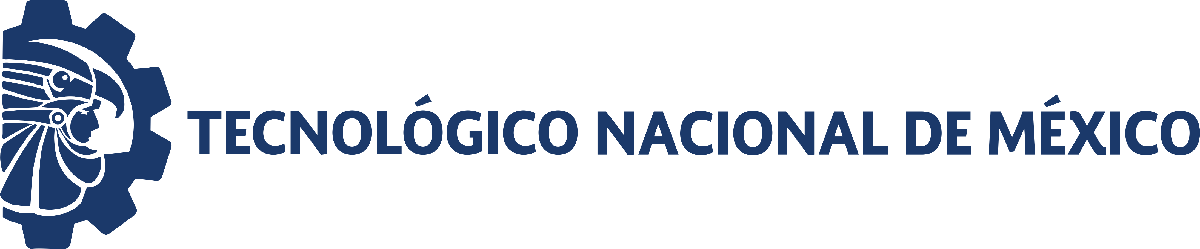                                 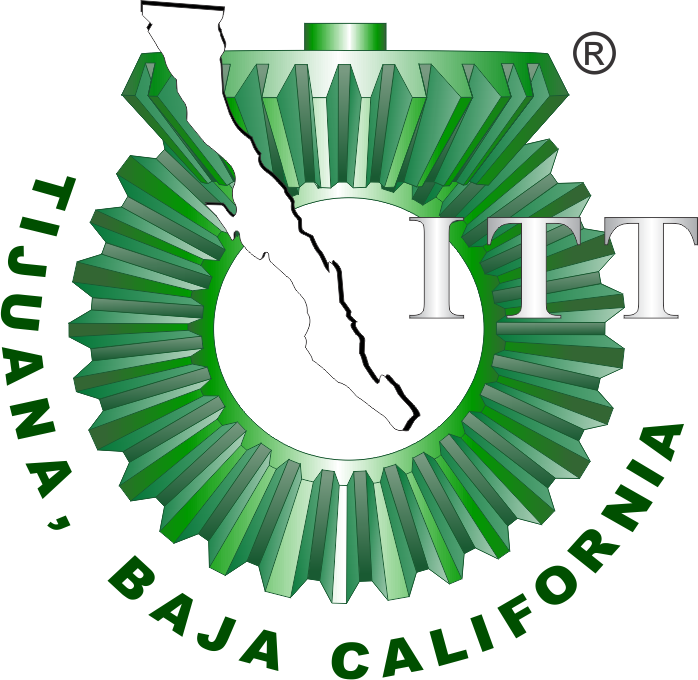

# Práctica dos: Sistema Musculoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

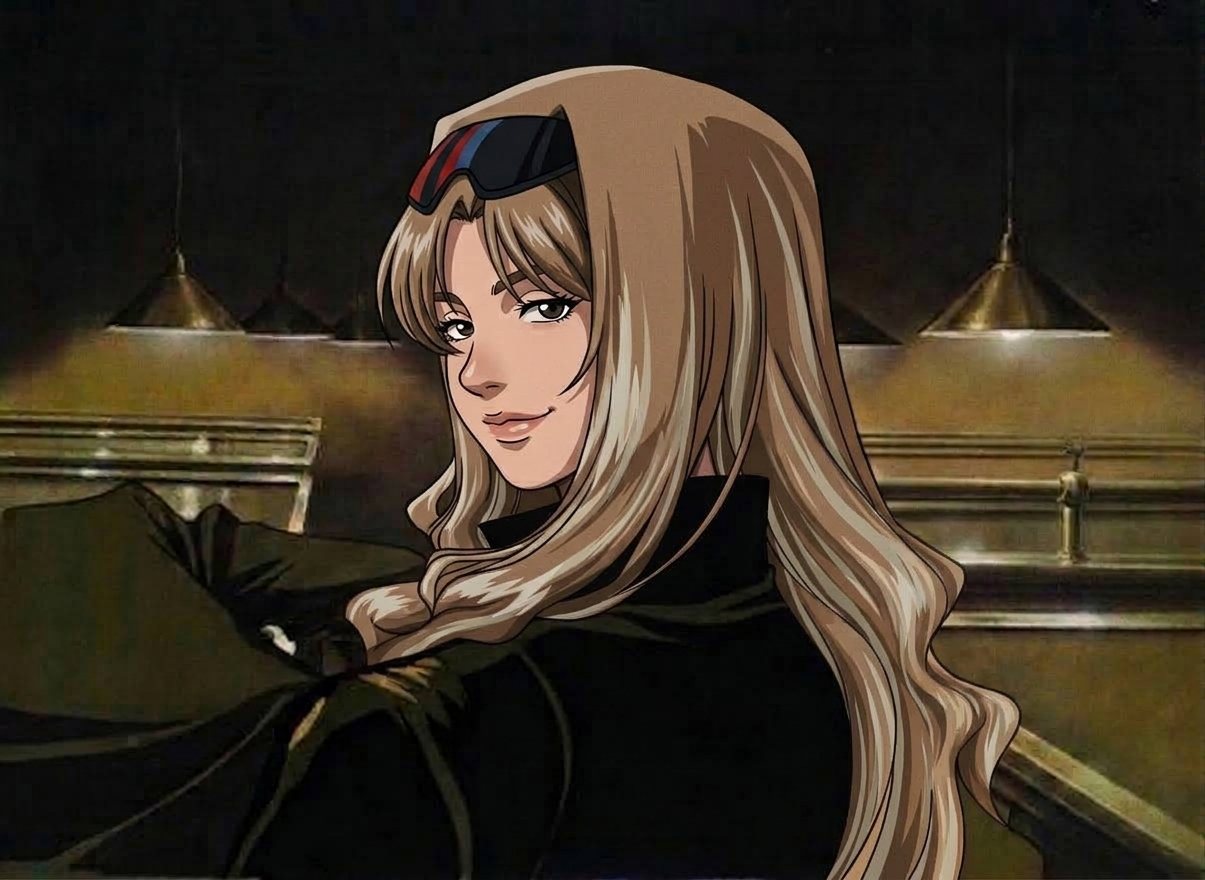

Nombre del alumno: **Nicole Vazquez Alvear**

Número de control: **C20210923**

Correo institucional: **lC20210923@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'P3';
open_system(file);
parameters.StopTime = '15'; 
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al impulso unitario

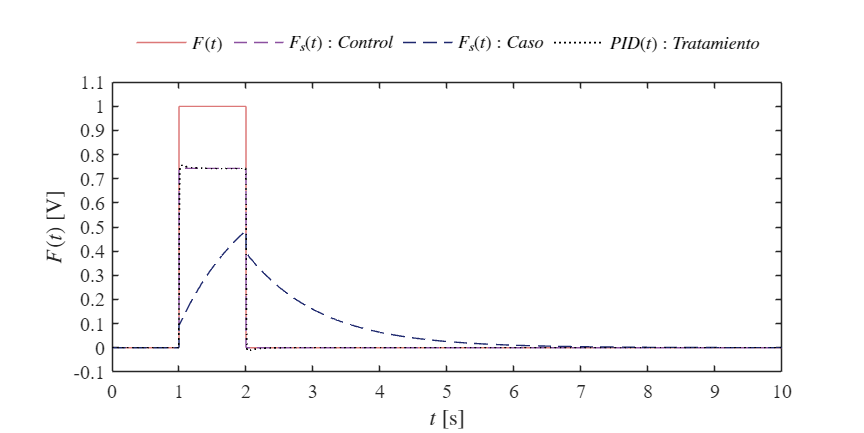

X = sim(file, parameters);
plotsignals(X.t, X.F, X.Fsx, X.Fsy, X.PID,'Respuestas')

## Función: Respuesta a la simulación

function plotsignals(t,x1,x2,x3,x4,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
clr1 = [220, 120, 120]/255;
clr2 = [140, 80, 160]/255;
clr3 = [30, 40, 110]/255;
clr4 = [0.5, 0.5, 0.5]/255;
order = [clr1;clr2;clr3;clr4]; colororder(order)

if signal == "Respuestas"
    plot(t,x1,'-','LineWidth',0.25,'Color',clr1) 
    plot(t,x2,'--','LineWidth',0.25,'Color',clr2) 
    plot(t,x3,'--','LineWidth',0.25,'Color',clr3) 
    plot(t,x4,':','LineWidth',1,'Color',clr4)
    L = legend('$F(t)$','$F_s(t):Control$','$F_s(t):Caso$','$PID(t):Tratamiento$');
end

set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,[signal,'matlab.pdf'],'ContentType','vector')
end
